% Skylar S and Kyle G and Eddie F
% DSP Fall 2024 HW 2

% Question 1
%This code segment extracts our data from the text file.
filename = 'C:\Users\Testing\Desktop\ECE 5530\Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt';
delimiterIn = ' ';
headerlinesIn = 1;
A = importdata(filename,delimiterIn,headerlinesIn);


% Question 2

fprintf('Question 2: \n');

Question 2: 


x = A.data(:,1);

y = A.data(:,2);

z = A.data(:,3);


S = sqrt(x.^2+y.^2+z.^2)

S =    53.3010
   51.9808
   52.3832
   49.2443
   47.2969
   47.9166
   48.3735
   48.9183
   50.2494
   49.5177




%Then we find signal energy

Signal_Energy=sum(S.^2)

Signal_Energy = 705068

% Question 3
fprintf('Question 3: \n');

Question 3: 


t = linspace(1,270,270)

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



windowSize = 3; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

my_smoothing_filter = filter(b,a,S);

Impulse = zeros(270,1);
Impulse(175)=1;
Impulse_response = filter(b,a,Impulse)

Impulse_response =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


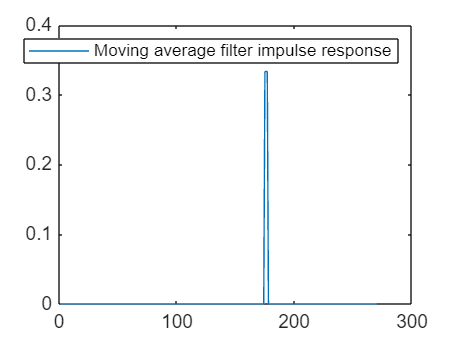

plot(t,Impulse_response)
legend('Moving average filter impulse response')



plot(t,S)

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

hold on
plot(t,my_smoothing_filter)
legend('Input Data','Filtered Data')


% Question 4
% Recursive system
fprintf('Question 4: \n');
xxr = x; % get the real-valued x vector
y2 = zeros(size(xxr)); % make an output vector the same size as x vector

yi = 0; % initial condition
y2(1) = 0.8*yi + xxr(1); % calculate output for time n=0 (using initial condition)

for i = 2:length(xxr) % calculate output recursively for n>=1 to length of vector x
y2(i) = .8*y2(i-1) + xxr(i);
end

% t = 0:1/32:(length(xxr)-1)*(1/32); % values are sampled at 32Hz according to the dataset documentation

figure; plot(t,x), hold on, plot(t,y2) % indicating that the first value in input or output sequences corresponds to time 0 when plotting
xlabel('time (n)'), ylabel('acceleration (m/{s^2})')
legend('X','y(n)')

% for i = 1:270
%    
%     result = recursive_function(i, x)
%     % Base case: if i == 1, return x(1)
%     if i == 1
%         result = x(1);
%     else
%         % Recursive case: 0.8 * Recursive(i-1) + x(i)
%         result = 0.8 * recursive_function(i-1, x) + x(i);
%     end
% end
% 
% 
% plot(Recursive,t)
% legend('Recursive System')












% Question 5
% Recursive system 2 
fprintf('Question 5: \n');
xxr2 = x; % get the real-valued x vector
y3 = zeros(size(xxr2)); % make an output vector the same size as x vector

yi = 0; % initial condition
y3(1) = (i/(i+1))*yi+(1/(i+1))*xxr2(1); % calculate output for time n=0 (using initial condition)

for i = 2:length(xxr2) % calculate output recursively for n>=1 to length of vector x

y3(i) = (i/(i+1))*y3(i-1)+(1/(i+1))*xxr2(i);

end

% t = 0:1/32:(length(xxr)-1)*(1/32); % values are sampled at 32Hz according to the dataset documentation

figure; plot(t,x), hold on, plot(t,y3) % indicating that the first value in input or output sequences corresponds to time 0 when plotting
xlabel('time (n)'), ylabel('acceleration (m/{s^2})')
legend('X','y(n)')

% What is this system computing?
% The first chunk of this system is a delay add function
% scaling to one over time- the second part is a diminishing function that
% decreased the value of the original function as time goes on. Essentially
% this system mimics follows the original function and then settles to a
% set value over time.


% Question 6
% Recursive system 3
fprintf('Question 6: \n');

xxr2 = x; % get the real-valued x vector
y4 = zeros(size(xxr2)); % make an output vector the same size as x vector

yi = 0; % initial condition
y4(1) = yi +xxr2(1); % calculate output for time n=0 (using initial condition)
y4(2) = yi- y4(1) +xxr2(2);
for i = 3:length(xxr2) % calculate output recursively for n>=1 to length of vector x

y4(i) =  y4(i-1) - y4(i-2) +xxr2(i);

end

% t = 0:1/32:(length(xxr)-1)*(1/32); % values are sampled at 32Hz according to the dataset documentation

figure; plot(t,x), hold on, plot(t,y4) % indicating that the first value in input or output sequences corresponds to time 0 when plotting
xlabel('time (n)'), ylabel('acceleration (m/{s^2})')
legend('X','y(n)')

% Test for LTI
fprintf('Test for LTI, Question 6: \n');

xxr2 = x; % get the real-valued x vector
y4 = zeros(size(xxr2)); % make an output vector the same size as x vector

yi = 0; % initial condition
y4(1) = yi +xxr2(1); % calculate output for time n=0 (using initial condition)
y4(2) = yi- y4(1) +xxr2(2);
for i = 3:length(xxr2) % calculate output recursively for n>=1 to length of vector x

y4(i) =  y4(i-1) - y4(i-2) +xxr2(i);

end

% t = 0:1/32:(length(xxr)-1)*(1/32); % values are sampled at 32Hz according to the dataset documentation

figure; plot(t,x), hold on, plot(t,y4) % indicating that the first value in input or output sequences corresponds to time 0 when plotting
xlabel('time (n)'), ylabel('acceleration (m/{s^2})')
legend('X','y(n)')


% Question 7
% Cross Correlated data 
fprintf('Question 7, Version A: \n'); %"flip" function used in "Version B" below.
Ccor1=xcorr(x,y);

Ccor2=xcorr(x,z);

Ccor3=xcorr(z,y);

t5 = linspace(1,539,539);
figure; plot(t5,Ccor1), hold on, plot(t5,Ccor2) , hold on, plot(t5,Ccor3) % indicating that the first value in input or output sequences corresponds to time 0 when plotting
xlabel('time (n)')
legend('Rxy','Rxz','Rzy')

fprintf('Question 7, Version B: \n');

Ccor4=conv(x,fliplr(y)); % indices 1 to 539 , fliplr applies a time fold on a row vector

Ccor5=conv(y,fliplr(x)); % cross correlation between y and x

Ccor6=conv(z,fliplr(y)); 
Ccor7=conv(y,fliplr(z)); 
Ccor8=conv(z,fliplr(x)); 
Ccor9=conv(x,fliplr(z)); 

figure; plot(1:539,Ccor4,'*-');hold on;plot(1:539,Ccor5,'ro:');hold on;plot(1:539,Ccor6,'m+--'); hold on;plot(1:539,Ccor7,'k.-.');hold on;plot(1:539,Ccor8,'ydiamond-.');hold on;plot(1:539,Ccor9,'gsquare-.');
title('cross correlation'); hold off % note the time fold relationship between rxy and ryx
xlabel('time (n)')
legend('Rxy','Ryx','Rzy','Ryz','Rzx','Rxz')




%Question 8
fprintf('Question 8: \n');
%Part A
fprintf('Part A, Question 8: \n');
% Because the Y signal is just the X signal with delay and noise, we can
% assume that our cross correlation function will filter out noise and
% leave us with an impulse where the functions match the highest. The time
% it takes for this impulse to appear is our delay.

%Part B
fprintf('Part B, Question 8: \n');

Xn = [-1,-1,-1,+1,+1,+1,+1,-1,+1,-1,+1,+1,-1,-1,+1,]

R = normrnd(0,sqrt(.01),1,200);
Xn(numel(R)) = 0;

Yn=0;
Yn(numel(R)) = 0;

% 
% xxr = x; % get the real-valued x vector
% y2 = zeros(size(xxr)); % make an output vector the same size as x vector
% 
 yi = 0; % initial condition
 Yn(1) = 0.9*yi + R(1); % calculate output for time n=0 (using initial condition)

t6 = linspace(1,200,200);

 for i = 21:length(Xn) % calculate output recursively for n>=1 to length of vector x
  Yn(i) = .9*Xn(i-20) + R(i);
 end

% 
% % t = 0:1/32:(length(xxr)-1)*(1/32); % values are sampled at 32Hz according to the dataset documentation
% 
figure; plot(t6,Yn), hold on, plot(t6,Xn) % indicating that the first value in input or output sequences corresponds to time 0 when plotting
xlabel('time (n)'), ylabel('Radr Signal')
% legend('X','y(n)')
% 
% 
% 



## Part C


fprintf('Part C, Question 8: \n');
Ccor4=xcorr(Yn,Xn);

t7 = linspace(1,399,399);

figure; plot(t7,Ccor4), hold on
xlabel('time (n)')
% legend('Rxy','Rxz','Rzy')

% We can see on our cross correlation that the x 
% value of our peak is at 20 points right of center, giving us our
% Delay value of 20 (220-200)


## Part D

fprintf('Part D, Question 8: \n');
Xn = [-1,-1,-1,+1,+1,+1,+1,-1,+1,-1,+1,+1,-1,-1,+1,]

R = normrnd(0,sqrt(.1),1,200);
Xn(numel(R)) = 0;

Yn=0;
Yn(numel(R)) = 0;

% 
% xxr = x; % get the real-valued x vector
% y2 = zeros(size(xxr)); % make an output vector the same size as x vector
% 
 yi = 0; % initial condition
 Yn(1) = 0.9*yi + R(1); % calculate output for time n=0 (using initial condition)

t6 = linspace(1,200,200);

 for i = 21:length(Xn) % calculate output recursively for n>=1 to length of vector x
  Yn(i) = .9*Xn(i-20) + R(i);
 end

% 
% % t = 0:1/32:(length(xxr)-1)*(1/32); % values are sampled at 32Hz according to the dataset documentation
% 
figure; plot(t6,Yn), hold on, plot(t6,Xn) % indicating that the first value in input or output sequences corresponds to time 0 when plotting
xlabel('time (n)'), ylabel('Radr Signal')
% legend('X','y(n)')
% 
% 
% 


%% Part C
Ccor4=xcorr(Yn,Xn);

t7 = linspace(1,399,399);

figure; plot(t7,Ccor4), hold on
xlabel('time (n)')
% legend('Rxy','Rxz','Rzy')

% We can see on our cross correlation that the x 
% value of our peak is at 20 points right of center, giving us our
% Delay value of 20 (220-200)


## Part D P2


fprintf('Part D, P2, Question 8: \n'); 
Xn = [-1,-1,-1,+1,+1,+1,+1,-1,+1,-1,+1,+1,-1,-1,+1,]

R = normrnd(0,sqrt(1),1,200);
Xn(numel(R)) = 0;

Yn=0;
Yn(numel(R)) = 0;

% 
% xxr = x; % get the real-valued x vector
% y2 = zeros(size(xxr)); % make an output vector the same size as x vector
% 
 yi = 0; % initial condition
 Yn(1) = 0.9*yi + R(1); % calculate output for time n=0 (using initial condition)

t6 = linspace(1,200,200);

 for i = 21:length(Xn) % calculate output recursively for n>=1 to length of vector x
  Yn(i) = .9*Xn(i-20) + R(i);
 end

% 
% % t = 0:1/32:(length(xxr)-1)*(1/32); % values are sampled at 32Hz according to the dataset documentation
% 
figure; plot(t6,Yn), hold on, plot(t6,Xn) % indicating that the first value in input or output sequences corresponds to time 0 when plotting
xlabel('time (n)'), ylabel('Radr Signal')
% legend('X','y(n)')
% 
% 
% 


%% Part C
Ccor4=xcorr(Yn,Xn);

t7 = linspace(1,399,399);

figure; plot(t7,Ccor4), hold on
xlabel('time (n)')
% legend('Rxy','Rxz','Rzy')

% We can see on our cross correlation that the x 
% value of our peak is at 20 points right of center, giving us our
% Delay value of 20 (220-200)






